# Logistic regression

Let's look at some examples of logistic regression for classification. The simplest case is in one dimension.

The negative log likelihood function, which is a cross-entropy error function, is defined at the end of this script.

Generate 1-dimensional synthetic data in two classes.

n = 10; % number of observations in each class
x1 = sqrt(2.5)*randn(n,1) - 2; % first class
x2 = sqrt(2.5)*randn(n,1) + 2; % second class
x = [x1; x2];
y = [zeros(n,1); ones(n,1)];

Define the negative log likelihood function, which we write as


$$E(w) = \sum_{i=1}^n \left\{ y_i \log(1+\exp(-s_i)) + (1-y_i) \log(1+\exp(s_i)) \right\}$$


where $s_i = w^T \phi(x_i)$ and $\phi(x)$ is the vector of basis functions. For the most basic case, $\phi(x) = [1, x]^T$. To vectorize the negative log likelihood function, `phi` will be the matrix whose $i$th column is $\phi(x_i)$.

phi = [ones(1,2*n); x'];
nll_fun = @(w) y'*log(1+exp(-w'*phi)') + (1-y)'*log(1+exp(w'*phi)');

Call a MATLAB built-in unconstrained optimization function to find `w`. The `fminunc` function only evaluates the objective function and does not need the gradient of the objective function. The function also takes an initial guess for `w`.

w = fminunc(nll_fun, [0 1]')


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


w =    -0.4438
    3.4445


Plot the logistic function corresponding to the weights that were optimized for the data.

xx = -5:.01:5;
ss = w(1)+w(2)*xx;
yy = 1./(1+exp(-ss));
clf
plot(xx,yy);
hold on

Also plot the original data.

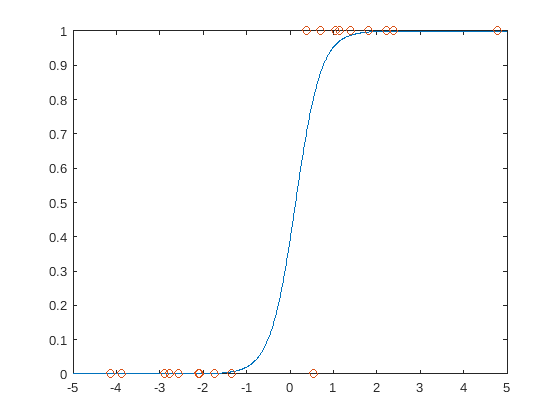

plot(x,y,'o');

Run this script several times to see how the shape of the logistic function changes depending on the data. You can also change the variance of the generated data, which would control how much overlap there is in the data between the two classes.

### Two-dimensional example

Generate 2-dimensional synthetic data in two classes.

x = [randn(20,2)-.8; randn(20,2)+.8];
y = [zeros(20,1); ones(20,1)];

Set the basis functions to give us a linear discriminant.

phi = [ones(1,2*20); x'];
nll_fun = @(w) y'*log(1+exp(-w'*phi)') + (1-y)'*log(1+exp(w'*phi)');

Call the optimizer. The negative log likehood function defined above will work for any number of dimensions.

w = fminunc(nll_fun, [0 0 0]')


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


w =    -0.1039
    1.6732
    1.0148


Compute the logistic function on a two-dimensional mesh.

xx = -4:.01:4;
yy = -4:.01:4;
[x1, x2] = meshgrid(xx, yy);
s = w(1) + w(2)*x1 + w(3)*x2;
Z = 1./(1+exp(-s));

Plot the logistic function and the data points.

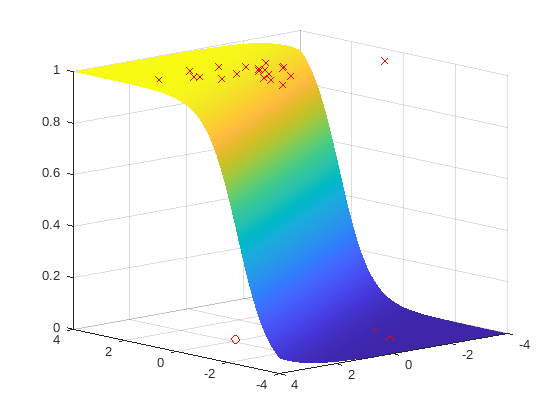

figure; clf
h = surf(xx, yy, Z);
set(h, 'edgecolor', 'none');
hold on
plot3(x( 1:20,1),x( 1:20,2),y( 1:20),'ro');
plot3(x(21:40,1),x(21:40,2),y(21:40),'rx');
view([-132.300 13.200])

Plot the decision surface, which is just a straight line for this 2-D example. Also plot the data points.

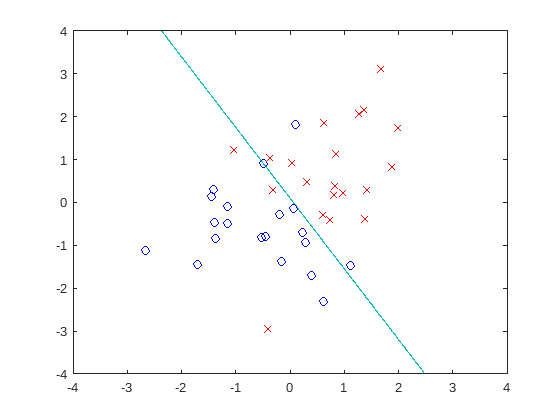

figure; clf
contour(xx, yy, Z, [0.5 0.5])
hold on
plot(x( 1:20,1),x( 1:20,2),'bo');
plot(x(21:40,1),x(21:40,2),'rx');

### Quadratic discriminants in two-dimensions

We'll use the same data in 2-D as the linear discriminant example above.

Set the basis functions to give us a quadratic discriminant.

phi = [ones(1,2*20); x'];
x1=x(:,1)'; % first component of data points
x2=x(:,2)'; % second component of data points x
phi = [ones(1,40)
       x1
       x2
       x1.*x1
       x1.*x2
       x2.*x2];
nll_fun = @(w) y'*log(1+exp(-w'*phi)') + (1-y)'*log(1+exp(w'*phi)');

Call the optimizer. The negative log likehood function defined above will work for any number of dimensions.

w = fminunc(nll_fun, [0 0 0 0 0 0]')


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


w =    -0.4905
    2.1397
    1.5497
    0.2313
    0.9346
    0.4984


Compute the logistic function on a two-dimensional mesh.

xx = -4:.01:4;
yy = -4:.01:4;
[x1, x2] = meshgrid(xx, yy);
s = w(1) + w(2)*x1 + w(3)*x2 + w(4)*x1.*x1 + w(5)*x1.*x2 + w(6)*x2.*x2;
Z = 1./(1+exp(-s));

Plot the logistic function and the data points.

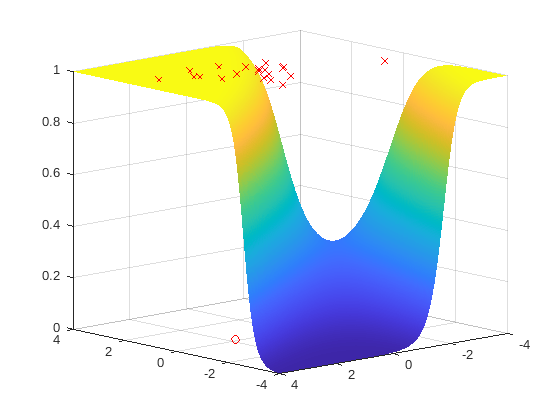

figure; clf
h = surf(xx, yy, Z);
set(h, 'edgecolor', 'none');
hold on
plot3(x( 1:20,1),x( 1:20,2),y( 1:20),'ro');
plot3(x(21:40,1),x(21:40,2),y(21:40),'rx');
view([-132.300 13.200])

Plot the decision surface and the data points.

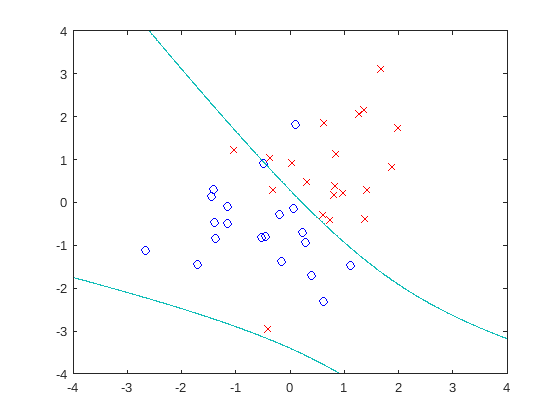

figure; clf
contour(xx, yy, Z, [0.5 0.5])
hold on
plot(x( 1:20,1),x( 1:20,2),'bo');
plot(x(21:40,1),x(21:40,2),'rx');

### Cubic discriminants in two-dimensions

Set the basis functions to give us a cubic discriminant.

phi = [ones(1,2*20); x'];
x1=x(:,1)'; % first component of data points
x2=x(:,2)'; % second component of data points x
phi = [ones(1,40)
       x1
       x2
       x1.*x1
       x1.*x2
       x2.*x2
       x1.^3
       x1.^2.*x2
       x1.*x2.^2
       x2.^3];
nll_fun = @(w) y'*log(1+exp(-w'*phi)') + (1-y)'*log(1+exp(w'*phi)');

Call the optimizer. The negative log likehood function defined above will work for any number of dimensions.

options = optimoptions('fminunc','MaxFunctionEvaluations',3000);
w = fminunc(nll_fun, [0 0 0 0 0 0 0 0 0 0]', options)


Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<stopping criteria details>


w =    -0.4696
   19.4631
   28.7597
   28.9942
   33.2811
   -8.4202
   18.4964
   40.5619
    5.4991
   -6.5633


Compute the logistic function on a two-dimensional mesh.

xx = -4:.01:4;
yy = -4:.01:4;
[x1, x2] = meshgrid(xx, yy);
s = w(1) + w(2)*x1 + w(3)*x2 + w(4)*x1.*x1 + w(5)*x1.*x2 + w(6)*x2.*x2 ...
         + w(7)*x1.^3 + w(8)*x1.^2.*x2 + w(9)*x1.*x2.^2 + w(10)*x2.^3;
Z = 1./(1+exp(-s));

Plot the decision surface and the data points.

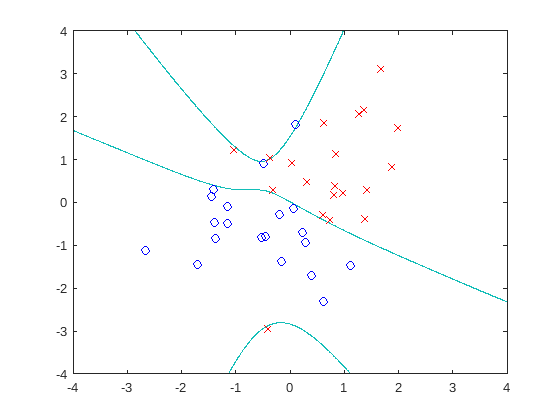

figure; clf
contour(xx, yy, Z, [0.5 0.5])
hold on
plot(x( 1:20,1),x( 1:20,2),'bo');
plot(x(21:40,1),x(21:40,2),'rx');

Plot the decision surface in a different way.

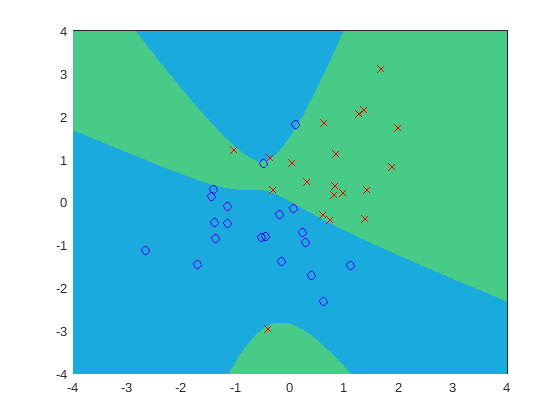

figure; clf
h = pcolor(xx, yy, sign(Z-0.5));
set(h, 'edgecolor', 'none');
caxis([-5 5]);
hold on
plot(x( 1:20,1),x( 1:20,2),'bo');
plot(x(21:40,1),x(21:40,2),'rx');